**Image Segmentation Using K-means Clustering Algorithm**

The goal of this assignment is to implement the K-means clustering algorithm for segmenting image data, considering the pixel RGB values along with their spatial coordinates. Students are required to write MATLAB code to process a given image by segmenting it into multiple regions based on the color and location information of the pixels.

clc; clear; close all;
% Reading and Preprocessing the Image
Baby = imread("baby.jpg");
baby = imresize(Baby,0.1);

% Feature Matrix Construction
[rows ,cols,~] = size(baby);
feature_matrix = zeros(rows*cols, 5);
for i = 1:rows
    for j = 1:cols
        rgb = double(reshape(baby(i, j, :), 1, 3));
        feature_matrix((i-1)*cols + j, :) = [rgb, i, j];
    end
end

% Implementing K-means Clustering Algorithm: 
K = 10;
max_iterations = 100;
[C,bestAssignment] = mykmeans(feature_matrix,K,max_iterations);

% Calculating the Average Color for Each Cluster
avg_colors = zeros(K, 3);
% 计算平均颜色
for k = 1:K
    avg_colors(k, :) = mean(feature_matrix(bestAssignment == k, 1:3), 1);
end

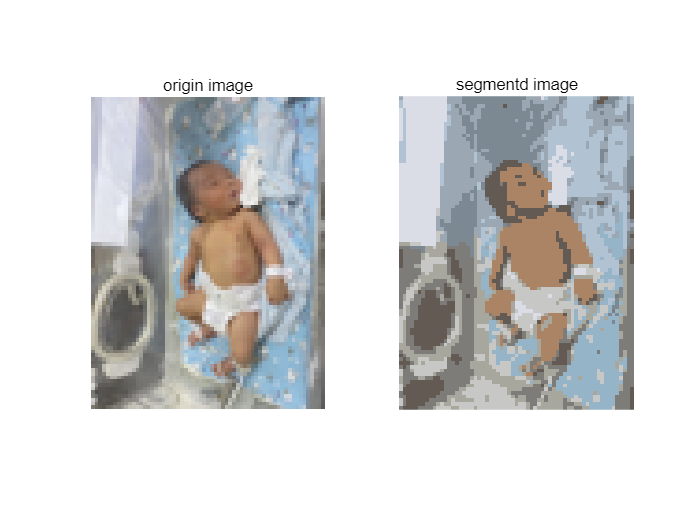

% Results Visualization
segmented_image = zeros(size(baby));
for i = 1:rows
    for j = 1:cols
        cluster_idx = bestAssignment((i-1) * cols + j);
        segmented_image(i, j, :) = avg_colors(cluster_idx, :);
    end
end
% 将分割图像转换回 uint8 类型
segmented_image = uint8(segmented_image);
% 显示图像
subplot(1, 2, 1);
imshow(baby);
title('origin image');
subplot(1, 2, 2);
imshow(segmented_image);
title('segmentd image');

function [C, bestAssignment] = mykmeans(X, K,max_iterations)
% Initialize cluster centers to be randomly sampled points
rng('shuffle');
[N, d] = size(X);
rp = randperm(N);
C = X(rp(1:K), :);
bestAssignment = zeros(N, 1);
while max_iterations
    lastAssignment = bestAssignment;
    % Assign each point to nearest cluster center
    mindist = Inf*ones(N, 1);
    for k = 1:K
        for n = 1:N
            dist = sum((X(n, :)-C(k, :)).^2);
            if dist < mindist(n)
               mindist(n) = dist;
               bestAssignment(n) = k;
            end
        end
    end
% break if assignment is unchanged
    if all(bestAssignment==lastAssignment)
        break; end
% Assign each cluster center to mean of
    for k = 1:K
    C(k, :) = mean(X(bestAssignment==k, :));
    end
end
end